# JTAG Server DE10-Lite MATLAB Interface

## Environment setup

clear;
clf;
% Add helper functions
addpath(genpath('Functions'));

% QUARTUS_ROOTDIR should be set by Quartus installation
% - If not change qpath to "[install_dir]/19.1/quartus"
qpath = getenv("QUARTUS_ROOTDIR");
server_script = "./SystemConsole/jtag_server.tcl";

% Spawn a JTAG service to the board
% - For this to work
%   - Include the JTAG IP in your design
%   - Compile the design and program your board
%   - Shut down the programmer tool
%   - Keep your board connected
launch_jtag_server(qpath, server_script);

% A new window will pop up saying Wait for clients
% - Now we can connect to the server so MATLAB can drive
local_ip_addr = "127.0.0.1"; % localhost
   local_port = 2540;        % static service port
      jtag_id = 0;           % Only one JTAG service, so this is 0
t = jtag_connect(local_ip_addr, local_port, jtag_id);

% Now we can use the TCP handle to read/write to the device
% NOTE: This cell only needs to be run once after programming

## Setup & Image formatting

clf;
% Task - Set this depending on task:
% 1 -- Random MNIST image
% 2 -- 256x256 test image
% 3 -- 128x128 test image
task = 3;
% Not used for Task I and Task III 
mode = 2;
% Only used for Task III
hist_bins = 8;
% For testType 1 & 2, you must specify an image from the
% ./Img/standard_test_images_small or ./Img/standard_test_images folders
test_2_3_img = "walkbridge.tif";

% Get test image as column vector of pixels 0-255
switch task
    % Get a random MNIST image, format
    case 1
        dim = 28;
        images = loadMNISTImages("./Img/handwriting-images");
        images_dims = size(images);
        rand_idx = randi([1, images_dims(2)], 1, 1);
        I = round(255.*images(:,rand_idx));
        I = reshape(I, [1, dim*dim]);
    case 2
        dim = 256;
        I = imread("./Img/standard_test_images/" + test_2_3_img, 1);
        I = imresize(I(:,:,1), [dim, dim]);
        I = reshape(I, [1, dim*dim]);
    case 3
        dim = 128;
        I = imread("./Img/standard_test_images/" + test_2_3_img, 1);
        I = imresize(I(:,:,1), [dim, dim]);
        I = reshape(I, [1, dim*dim]);
    otherwise
        task=1;
        dim = 28;
        images = loadMNISTImages("./Img/handwriting-images");
        images_dims = size(images);
        rand_idx = randi([1, images_dims(2)], 1, 1);
        I = round(255.*images(:,rand_idx));
end

disp("Image used in this test:")

Image used in this test:


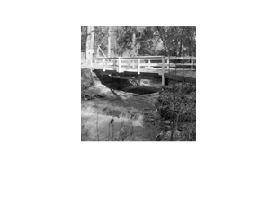

imshow(mat2gray(reshape(I, [dim, dim])))


% Create hex data for simulation
%   - If something is wrong after this MATLAB run you can load a 28x28


% Memory map - will not change throughout tasks
data_base_addr       = 0x00000000;
dim_base_addr        = 0x00040800;
start_base_addr      = 0x00040810;
ready_base_addr      = 0x00040820;
mode_base_addr       = 0x00040830;
hist_bins_base_addr  = 0x00040840;
hist_base_addr       = 0x00050000;

## Drive Image

% FPGA image tx/rx
%   - (1) 'dim' is updated
%   - (2) 'mode' is updated - no effect for Task I and Task III
%   - (3) 'ready' is held at '0' until image is transferred
%   - (4) once 'start' is set to '1' image is read from FPGA (ready is set to '0')
%   - Large images (>10KB) are sent in chunks to avoid stalls
%       - Chunking does not effect the overall function as ready is held at 0 during transfers

% System may hang if:
%   - Start/Ready behavior is not handled properly
%   - Dimensions are not handled or there is a forever loop keeping start from being set to '1'

[ret_pixels, o_fpga_hist] = write_readback_col...
    (t, I, ... 
    data_base_addr, ready_base_addr, ...
    start_base_addr, dim_base_addr, ... 
    mode_base_addr, hist_base_addr, ...
    hist_bins_base_addr, ...
    dim, mode, hist_bins);

O_FPGA_PIX = reshape(ret_pixels, [dim, dim]);
disp("FPGA transaction complete!")

FPGA transaction complete!


## Check Result - Useful for Part I (you can make your own checks for Parts II-III)

Success! FPGA returns expected histogram!


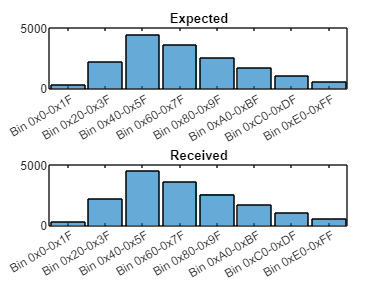

clf;
% Check result
switch task
    case 1
        % For part I, no change, pixels are passed through
        O_EXPECTED_PIX = I;
    % We intentionally obfuscate this function
    case 2
        O_EXPECTED_PIX = obfuscated_bit_model(I, mode);
    case 3
        hist_exp = histc(reshape(double(I),[],1), linspace(0,256,hist_bins+1));
        hist_exp = hist_exp(1:hist_bins);
end

if task == 1 || task == 2
    % Format expected, input, and FPGA output images for displaying
    O_EXPECTED_PIX = reshape(O_EXPECTED_PIX, [dim, dim]);
    I_DISP = mat2gray(reshape(I, [dim, dim]));
    O_FPGA_PIX_DISP = mat2gray(reshape(O_FPGA_PIX, [dim, dim]));
    O_EXPECTED_PIX_DISP = mat2gray(O_EXPECTED_PIX);
    
    % Show images
    f = figure();
    clf;
    subplot(3,1,1); imshow(I_DISP); xlabel("Input Image");
    subplot(3,1,2), imshow(O_FPGA_PIX_DISP); xlabel("FPGA Output");
    subplot(3,1,3), imshow(O_EXPECTED_PIX_DISP); xlabel("Expected Output");
    
    % Save plot as png for reporting 
    % NOTE: You may want to clear the OutputImg folder periodically as
    %       timestamped images are retained to avoid data loss.
    d = erase(string(datetime("now")), ' ');
    d = strrep(d, ":", ".");
    exportgraphics(f,'./OutputImg/test_result' + d + '_img.png', 'Resolution',300);
    % Compare output pixels to expected pixels
    if(O_EXPECTED_PIX == O_FPGA_PIX)
        disp("Success! FPGA returns expected image!");
    else 
        disp("Error! Mismatch between FPGA and expected image!");
        disp("I output dump:");
        disp(reshape(I, [dim, dim]));
        disp("FPGA output dump:");
        disp(O_FPGA_PIX);
        disp("Expected output dump:");
        disp(O_EXPECTED_PIX);
        disp("Difference output dump:");
        mat_diff = O_EXPECTED_PIX-O_FPGA_PIX;
        disp(mat_diff);
    end
else
    f = figure();
    cats = create_categories(hist_bins);
    o_fpga_hist = o_fpga_hist(1:hist_bins);
    if o_fpga_hist == hist_exp'
        disp("Success! FPGA returns expected histogram!");
        subplot(2,1,1);
        histogram('BinCounts', o_fpga_hist, 'Categories', cats);
        title('Expected');
        subplot(2,1,2); 
        histogram('BinCounts', hist_exp, 'Categories', cats );
        title('Received');
    else
        disp("Error! FPGA returns unexpected histogram!");
        mat_diff = o_fpga_hist - hist_exp';
        subplot(3,1,1);
        histogram('BinCounts', hist_exp, 'Categories', cats);
        title('Expected');
        subplot(3,1,2);
        histogram('BinCounts', o_fpga_hist, 'Categories', cats );
        title('Received');
        subplot(3,1,3);
        histogram('BinCounts', abs(mat_diff), 'Categories', cats );
        title('Difference');
    end
    d = erase(string(datetime("now")), ' ');
    d = strrep(d, ":", ".");
    exportgraphics(f,'./OutputImg/test_result' + d + '_hist.png', 'Resolution',300);
end